## thresholding

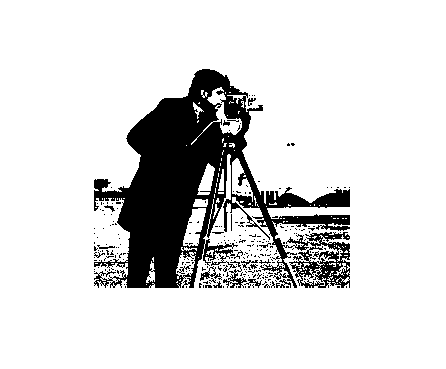

cm = imread('cameraman.tif');
cm_t = cm > 120;
imshow(cm_t)

brightness

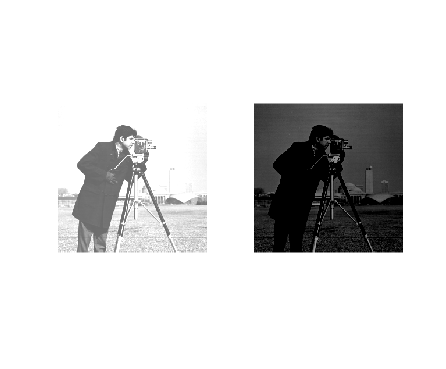

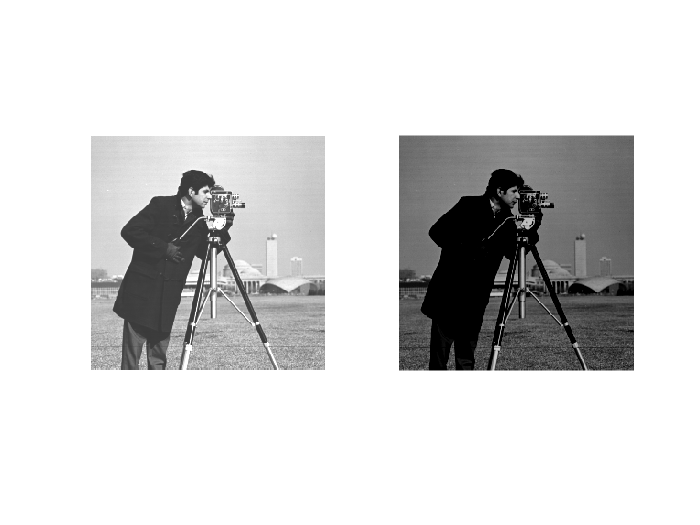

cm_d = double(cm);

figure(1)
cm_d1 = cm_d + 100;
subplot(1, 2, 1); imshow(uint8(cm_d1))        % a lighter img

cm_d2 = cm_d - 100;
subplot(1, 2, 2); imshow(uint8(cm_d2))        % a darker img

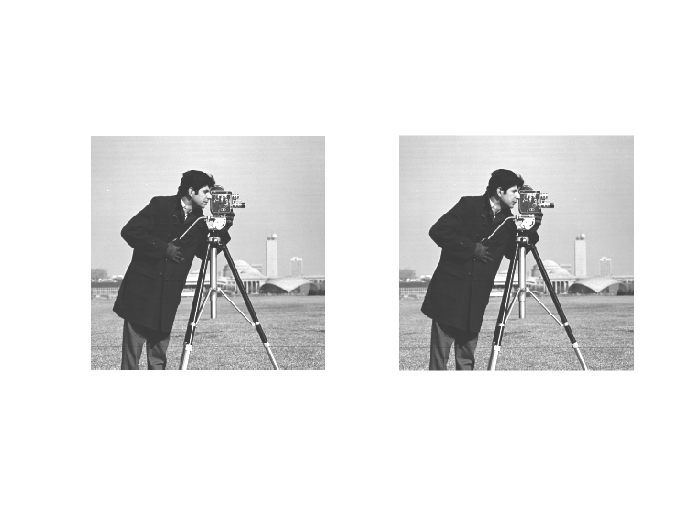

% or                   no double no uint8
figure(2)
cm_d3 = imadd(cm, 50);
subplot(1, 2, 1); imshow(cm_d3) 

cm_d4 = imsubtract(cm, -50);
subplot(1, 2, 2); imshow(cm_d4) 

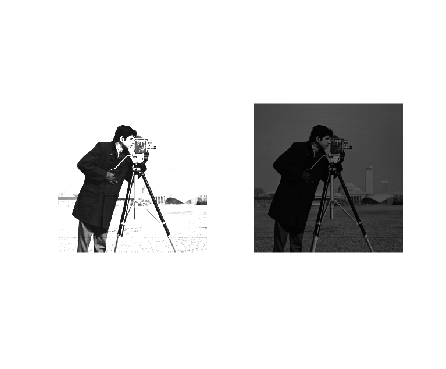

% or
figure(3)
cm_d5 = immultiply(cm, 2.4);
subplot(1, 2, 1); imshow(cm_d5) 

cm_d6 = imdivide(cm, 2.4);
subplot(1, 2, 2); imshow(cm_d6)

complement

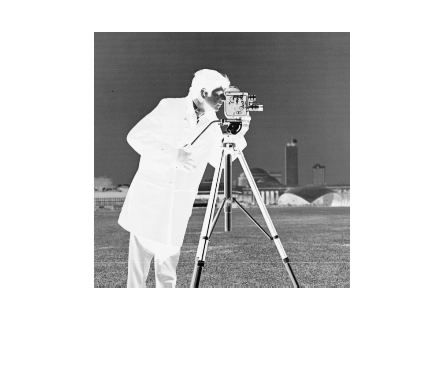

cm_c = imcomplement(cm);
figure; imshow(cm_c)

## logarithm and expotional(power) operator 

deal with too dark img,  gray degree

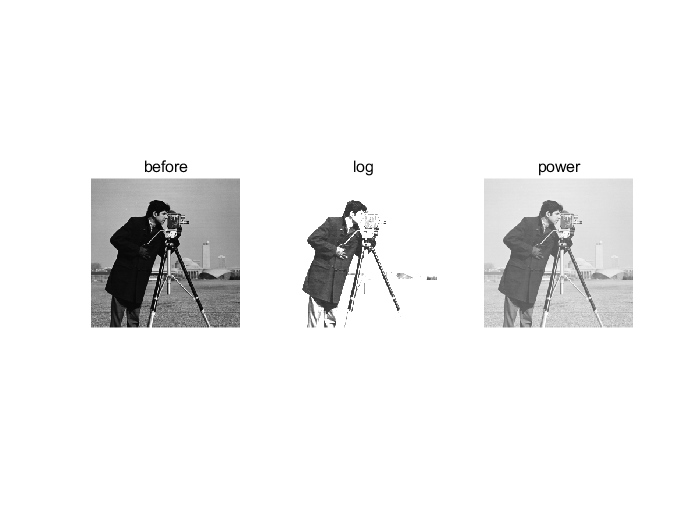

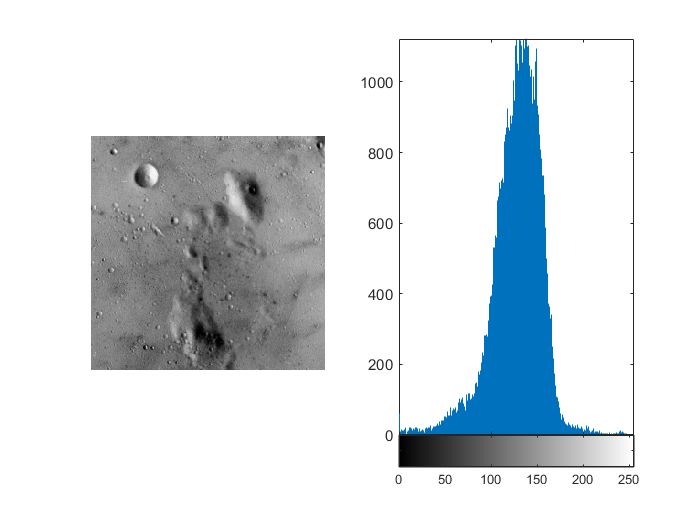

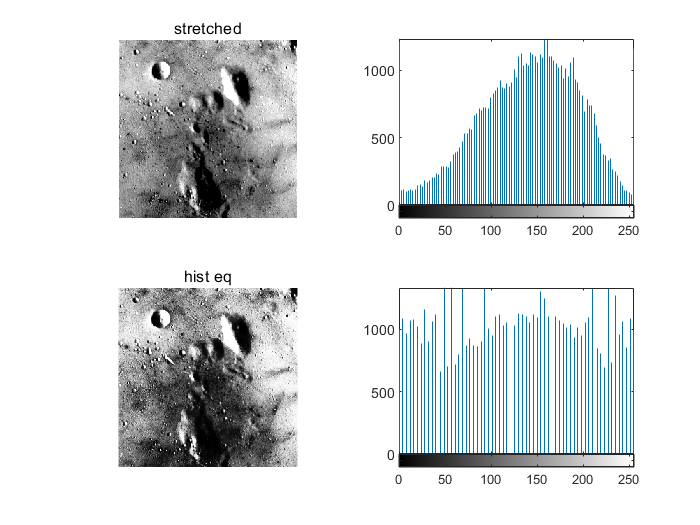

clear; clc;
cm = imread('cameraman.tif');
cm_d = im2double(cm);

x = cm_d;   % whatever, 0 is ok, just initialize it
y = cm_d;
[rows, columns] = size(cm_d);
log_fac = 6;
power_fac = 0.3;

for i = 1:rows
    for j = 1:columns
        x(i, j) = log_fac * log(1 + cm_d(i, j));
        y(i, j) = cm_d(i, j) ^ power_fac;
    end
end

figure;
subplot(1, 3, 1); imshow(cm_d); title("before")
subplot(1, 3, 2); imshow(x); title('log')
subplot(1, 3, 3); imshow(y); title("power")